# Chapter 1: Calibration of Output Devices

## 1.1: Plot TRCs (Tone-Reproduction Curves) for RGB channels

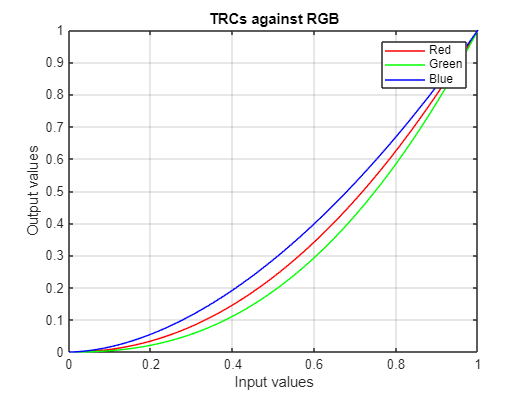

% Tone Reproduction curves show the relationship between luminence and
% color and display luminance

% Load TRC data
load('TRC_display.mat');
input_values = linspace(0, 1, 101); % Linear input values (R=G=B=[0: 0.01: 1] this the same I think??)

% Plot TRC for RGB
figure;
plot(input_values, TRCr, 'r', input_values, TRCg, 'g', input_values, TRCb, 'b');
xlabel('Input values');
ylabel('Output values');
title('TRCs against RGB');
legend('Red', 'Green', 'Blue'); grid on;

## 1.2: Linearization using interpolation (Check hints for inverse interpolation)

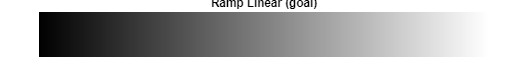

% Load images
load('Ramp_linear.mat');
load('Ramp_display.mat');

% Show Ramp_linear
figure;
imshow(Ramp_linear);
title('Ramp Linear (goal)');

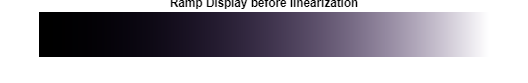


% Show Ramp_display before linearization
figure;
imshow(Ramp_display);
title('Ramp Display before linearization');

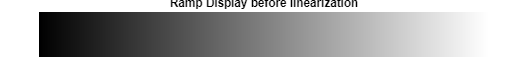


% linearization to image
Ramp_linearized(:,:,1) = interp1(TRCr, input_values, Ramp_display(:,:,1), 'pchip'); % interploation from tips
Ramp_linearized(:,:,2) = interp1(TRCg, input_values, Ramp_display(:,:,2), 'pchip');
Ramp_linearized(:,:,3) = interp1(TRCb, input_values, Ramp_display(:,:,3), 'pchip');

% Display linearized image
figure;
imshow(Ramp_linearized);
title('Ramp Display before linearization');

## 1.3: Gamma correction

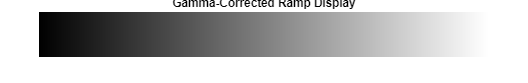

% Define gamma
gamma_R = 2.1; 
gamma_G = 2.4;
gamma_B = 1.8;

% Gamma correction using eq 4, can't make Dmax work
Ramp_gamma_corrected(:,:,1) = Ramp_display(:,:,1) .^ (1/gamma_R);
Ramp_gamma_corrected(:,:,2) = Ramp_display(:,:,2) .^ (1/gamma_G);
Ramp_gamma_corrected(:,:,3) = Ramp_display(:,:,3) .^ (1/gamma_B);

% Display the gamma-corrected image
figure;
imshow(Ramp_gamma_corrected);
title('Gamma-Corrected Ramp Display');

# Chapter 2: Spectral Forward Model of the Output Device

## 2.1: Load and plot spectral data for DLP projector

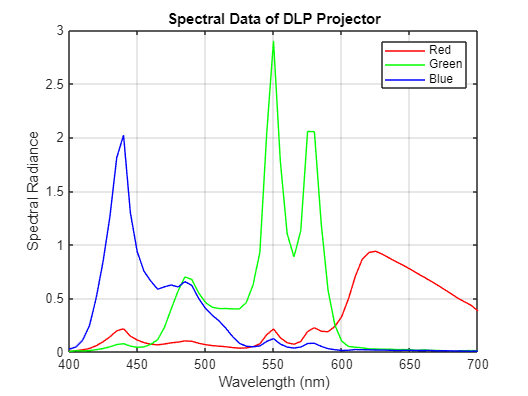

load('DLP.mat'); % Matrix DLP (spectra radiance for R, G, B)
wavelengths = 400:5:700; % wavelengths from instruction

figure;
plot(wavelengths, DLP);
xlabel('Wavelength (nm)');
ylabel('Spectral Radiance');
title('Spectral Data of DLP Projector');
colororder(["#FF0000";"#00FF00";"#0000FF"])
legend('Red', 'Green', 'Blue'); grid on;

## 2.2: Compute spectral output for raw camera data

load('RGB_raw.mat'); % Camera raw RGB values
SRGB = DLP * RGB_raw; % Compute spectral radiance output for 20 color samples, eq 2

% Convert spectral radiance to XYZ values
load('xyz.mat');
normFactor = 100 / sum(xyz(:,2)); % Compute normalization factor using D65 (y = 100) white point (eq 7 in lab1, section 3.1)
XYZ = normFactor * (xyz' * SRGB); % eq 8 from lab1

% Load reference XYZ values
load('XYZ_ref.mat'); % Reference XYZ values

% Compute delta Eab color differences
DeltaEab = sqrt(sum((XYZ - XYZ_ref).^2, 1));
mean_DE = mean(DeltaEab);
max_DE = max(DeltaEab);

% Display mean and max delta Eab color differences
fprintf('Mean delta Eab: %.2f\n', mean_DE);

Mean delta Eab: 14.48


fprintf('Max delta Eab: %.2f\n', max_DE);

Max delta Eab: 37.23


## 2.3: Compute spectral output for calibrated camera data

load('RGB_cal.mat'); % Load calibrated camera values
SRGB_cal = DLP * RGB_cal; % Compute spectral radiance output for calibrated input, eq 2

% Convert spectral radiance to XYZ values
XYZ_cal = normFactor * (xyz' * SRGB_cal);

% Compute delta Eab color differences
DeltaEab_cal = sqrt(sum((XYZ_cal - XYZ_ref).^2, 1));
mean_DE_cal = mean(DeltaEab_cal);
max_DE_cal = max(DeltaEab_cal);

% Display mean and max ΔEab color differences for calibrated input
fprintf('Mean delta Eab for calibrated input: %.2f\n', mean_DE_cal);

Mean delta Eab for calibrated input: 10.88


fprintf('Max delta Eab for calibrated input: %.2f\n', max_DE_cal);

Max delta Eab for calibrated input: 28.28


# Chapter 3: Inverse Characterization of the Output Device

## 3.1: Compute transformation matrix ACRT (Using Eq. 3 for XYZ-RGB transformation)

ACRT = xyz' * DLP; % XYZ values for primaries at max intensity
inv_ACRT = inv(ACRT); % Compute inverse transformation


## 3.2: Convert target XYZ to RGB (Applying inverse transformation from Eq. 3)

RGB_projector = inv_ACRT * XYZ_ref;


## 3.3: Clip values to [0,1] range (Ensuring valid RGB values inside device gamut)

RGB_projector = max(0, min(1, RGB_projector));


## 3.4: Predict spectral output (Using Eq. 2 to compute final spectral radiance)

SRGB_predicted = DLP * RGB_projector;


## 3.5: Gamut Visualization (Using provided function plot_chrom_sRGB)

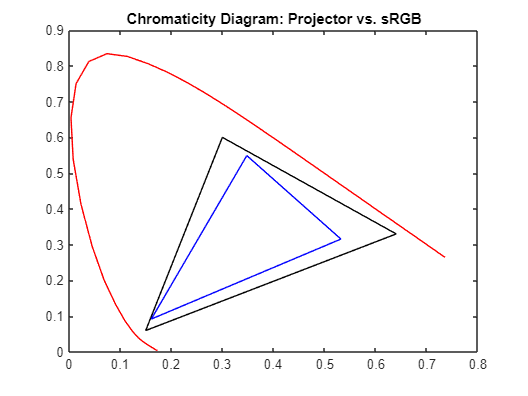

plot_chrom_sRGB(ACRT);
title('Chromaticity Diagram: Projector vs. sRGB');

# Chapter 4: Spectral Comparison for a Single Color

## 4.1: Select an example color sample (e.g., object 8)

idx = 8;
original_spectrum = chips20(:, idx); % Original under D65
reproduced_spectrum = SRGB(:, idx);

## 4.2: Plot comparison

figure;
plot(wavelengths, original_spectrum, 'k', wavelengths, reproduced_spectrum, 'r');

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

xlabel('Wavelength (nm)'); ylabel('Spectral Radiance');
title('Spectral Comparison: Original vs. Projected');
legend('Original', 'Projected'); grid on;
